**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221**

**4. Perform 10 different neural network trainings, each using different random seeds, and discuss the variability that arises in the produced interclass decision boundaries.**

The 10 different plots have been saved in the neural network folder attached in the zipped folder

clear;
clc;
%loading variables from exercise 1
a = load("ex1.mat")

a = struct with fields:
          Da: [3×3 double]
          Db: [3×3 double]
          Dc: [3×3 double]
           K: 1000
          Va: [3×3 double]
          Vb: [3×3 double]
          Vc: [3×3 double]
           W: [1000×3 double]
         ans: [-2.0000 -5.0000 -5]
    filename: 'ex1.mat'
         muA: [3×1 double]
         muB: [3×1 double]
         muC: [3×1 double]
         muT: [3×1 double]
      sigmaA: [3×3 double]
      sigmaB: [3×3 double]
      sigmaC: [3×3 double]
      sigmaT: [3×3 double]
    testdata: [50×3 double]
           y: [1000×3 double]
           z: [1000×3 double]


boundary_1 =    -3.2550    7.7852  -15.0000
   -3.2550    7.7852  -14.7651
   -3.2550    7.7852  -14.5302
   -1.8456    6.6107  -12.8859
   -1.8456    6.6107  -12.6510
   -1.6107    6.3758  -15.0000
   -1.6107    6.3758  -14.7651
   -1.6107    6.3758  -14.5302
   -1.6107    6.3758  -14.2953
   -1.6107    6.3758  -14.0604


boundary_2 =   -15.0000  -14.5302    8.4899
  -15.0000  -11.2416    2.3826
  -15.0000   -6.7785   -1.1409
  -15.0000   -5.6040   -1.8456
  -15.0000   -5.1342   -2.0805
  -15.0000   -3.7248   -2.5503
  -15.0000   -2.0805   -2.7852
  -15.0000   -1.8456   -2.7852
  -15.0000    1.2081   -3.0201
  -15.0000    2.1477   -3.2550


boundary_3 =    -5.3691   20.0000  -15.0000
   -5.1342   19.2953  -14.7651
   -5.1342   20.0000  -14.5302
   -4.8993   18.3557  -15.0000
   -4.8993   18.5906  -14.7651
   -4.8993   18.8255  -14.5302
   -4.8993   19.2953  -14.2953
   -4.6644   18.1208  -14.5302
   -4.6644   18.3557  -14.2953
   -4.6644   18.5906  -14.0604


boundary_1 =     1.6779   13.8926  -14.2953
    1.6779   14.1275  -14.5302
    1.9128   12.4832  -12.8859
    2.1477   14.1275  -14.7651
    2.1477   14.3624  -15.0000
    2.3826   12.9530  -13.5906
    2.6174   12.2483  -12.8859
    2.8523   11.7785  -12.4161
    2.8523   14.1275  -15.0000
    3.0872    9.6644   -9.5973


boundary_2 =   -15.0000  -11.2416    8.4899
  -15.0000   -8.1879    5.6711
  -15.0000   -6.5436    4.7315
  -15.0000   -5.1342    4.2617
  -15.0000   -2.0805    2.3826
  -15.0000    0.2685    0.0336
  -15.0000    1.4430   -1.3758
  -15.0000    3.7919   -3.9597
  -15.0000    4.7315   -4.6644
  -15.0000    6.8456   -6.3087


boundary_3 =     1.2081   13.8926  -12.8859
    1.2081   14.1275  -13.1208
    1.2081   14.3624  -13.3557
    1.2081   14.5973  -13.5906
    1.2081   14.8322  -13.8255
    1.4430   12.2483  -11.2416
    1.4430   13.1879  -11.9463
    1.4430   13.4228  -12.1812
    1.4430   14.5973  -13.3557
    1.4430   14.8322  -13.5906


boundary_1 =     3.5570  -14.0604    4.9664
    3.7919   12.0134   -2.0805
    3.7919   13.1879   -2.3154
    3.7919   13.4228   -2.3154
    3.7919   13.6577   -2.3154
    3.7919   13.8926   -2.3154
    4.0268  -12.8859    4.7315
    4.0268  -12.6510    4.7315
    4.0268   10.1342   -1.8456
    4.2617    9.1946   -1.8456


boundary_2 =   -15.0000  -15.0000    5.2013
  -15.0000  -14.7651    5.2013
  -15.0000  -11.2416    5.2013
  -15.0000   -9.3624    4.7315
  -15.0000   -8.1879    4.2617
  -15.0000   -6.7785    3.5570
  -15.0000   -6.3087    3.3221
  -15.0000   -5.8389    3.0872
  -15.0000   -4.4295    2.6174
  -15.0000   -0.4362    2.3826


boundary_3 =     1.9128  -15.0000   17.8859
    1.9128  -15.0000   18.1208
    1.9128  -15.0000   18.3557
    1.9128  -14.7651   18.3557
    1.9128  -14.7651   18.5906
    1.9128  -14.7651   18.8255
    1.9128  -14.5302   18.8255
    1.9128  -14.5302   19.0604
    1.9128  -14.5302   19.2953
    1.9128  -14.2953   19.0604


boundary_1 =    -5.6040   14.5973  -15.0000
   -4.6644   14.5973  -15.0000
   -4.4295   14.5973  -15.0000
   -4.1946   14.1275  -13.5906
   -4.1946   14.3624  -14.2953
   -4.1946   14.5973  -15.0000
   -3.7248   14.3624  -14.0604
   -3.7248   14.5973  -14.7651
   -3.4899   14.1275  -13.1208
   -3.2550   14.1275  -12.8859


boundary_2 =   -15.0000   -7.9530    1.4430
  -15.0000   -7.7181    1.2081
  -15.0000   -7.2483    0.7383
  -15.0000   -7.0134    0.5034
  -15.0000   -4.1946   -2.0805
  -15.0000    1.9128   -5.6040
  -15.0000    4.2617   -7.4832
  -15.0000    7.3154  -11.4765
  -14.7651  -15.0000   10.8389
  -14.7651  -12.8859    8.9597


boundary_3 =    -6.7785   20.0000  -14.7651
   -6.5436   19.0604  -14.7651
   -6.3087   15.7718  -14.5302
   -6.3087   16.0067  -14.5302
   -6.3087   18.5906  -14.5302
   -6.3087   19.2953  -14.2953
   -6.0738   16.0067  -14.2953
   -6.0738   18.1208  -14.2953
   -6.0738   18.3557  -14.2953
   -6.0738   19.0604  -14.0604


boundary_1 =    -7.7181   15.3020  -14.7651
   -7.4832   14.5973  -13.5906
   -7.4832   14.8322  -14.0604
   -7.2483   15.0671  -15.0000
   -7.0134   13.8926  -12.8859
   -7.0134   14.1275  -13.3557
   -7.0134   14.3624  -13.8255
   -7.0134   14.5973  -14.2953
   -6.5436   13.1879  -12.1812
   -6.5436   14.1275  -14.0604


boundary_2 =   -15.0000  -14.2953    6.3758
  -15.0000  -13.5906    6.1409
  -15.0000  -12.8859    5.9060
  -15.0000  -12.1812    5.6711
  -15.0000  -11.4765    5.4362
  -15.0000   -8.6577    2.6174
  -15.0000   -8.1879   -0.2013
  -15.0000   -7.2483   -2.5503
  -15.0000   -4.8993   -4.6644
  -15.0000   -2.5503   -6.0738


boundary_3 =   -15.0000   19.5302  -10.7718
  -15.0000   19.5302  -10.5369
  -15.0000   19.5302  -10.3020
  -15.0000   19.5302  -10.0671
  -15.0000   20.0000  -11.4765
  -15.0000   20.0000   -9.8322
  -14.7651   19.5302  -10.7718
  -14.7651   19.5302  -10.5369
  -14.7651   19.5302  -10.3020
  -14.7651   19.5302  -10.0671


boundary_1 =     4.7315    8.4899   -0.9060
    4.7315    8.7248   -1.1409
    4.7315    8.9597   -1.3758
    4.7315    9.1946   -1.6107
    4.7315    9.4295   -1.8456
    4.7315    9.6644   -2.0805
    4.7315   11.0738   -6.3087
    4.7315   11.0738   -6.0738
    4.9664    6.6107    0.2685
    4.9664    9.6644   -2.7852


boundary_2 =   -15.0000  -12.6510   20.0000
  -15.0000  -10.3020   16.7114
  -15.0000   -9.3624   14.8322
  -15.0000   -8.6577   12.0134
  -15.0000   -8.4228    8.9597
  -15.0000   -8.1879    8.2550
  -15.0000   -7.7181    7.5503
  -15.0000   -7.4832    7.3154
  -15.0000   -7.2483    7.0805
  -15.0000   -7.0134    6.8456


boundary_3 =     4.4966    8.7248    0.7383
    4.7315    5.2013    3.0872
    4.7315    6.6107    3.3221
    4.7315    7.3154    2.8523
    4.7315    8.7248    1.6779
    4.7315    8.9597    1.4430
    4.7315    9.8993    0.2685
    4.9664  -13.5906   19.5302
    4.9664    3.7919    4.4966
    4.9664    5.2013    4.9664


boundary_1 =     4.9664    9.1946   -1.6107
    5.2013    7.5503   -1.1409
    5.2013    8.0201   -1.3758
    5.2013    9.6644   -1.8456
    5.2013   11.3087   -1.8456
    5.4362    8.2550   -1.6107
    5.4362    8.9597   -1.8456
    5.4362   10.6040   -2.0805
    5.6711    6.6107   -0.9060
    5.6711   12.2483   -2.0805


boundary_2 =   -15.0000  -14.7651    2.3826
  -15.0000  -13.1208    2.3826
  -15.0000   -9.3624    2.3826
  -15.0000   -7.7181    1.9128
  -15.0000   -7.0134    1.4430
  -15.0000   -6.7785    1.2081
  -15.0000   -6.5436    0.9732
  -15.0000   -6.3087    0.7383
  -15.0000   -5.3691   -0.4362
  -15.0000   -3.7248   -2.0805


boundary_3 =     4.4966    8.9597   -0.2013
    4.4966    9.1946   -0.2013
    4.4966    9.4295   -0.2013
    4.4966    9.6644   -0.2013
    4.7315    8.0201    0.0336
    4.7315    8.7248    0.2685
    4.7315    9.8993    0.2685
    4.7315   11.3087   -0.4362
    4.9664    7.7852    0.5034
    4.9664    8.2550    0.7383


boundary_1 =    -1.3758   20.0000  -10.0671
   -1.3758   20.0000   -9.8322
   -1.3758   20.0000   -9.3624
   -1.3758   20.0000   -9.1275
   -1.3758   20.0000   -8.8926
   -1.1409   19.5302   -9.5973
   -1.1409   19.5302   -8.6577
   -1.1409   19.5302   -8.4228
   -1.1409   19.7651  -10.0671
   -1.1409   19.7651   -8.1879


boundary_2 =   -15.0000  -14.7651    2.1477
  -15.0000  -13.8255    1.9128
  -15.0000  -10.3020    1.9128
  -15.0000  -10.0671    1.9128
  -15.0000   -8.8926    1.9128
  -15.0000   -8.6577    1.9128
  -15.0000   -7.4832    1.6779
  -15.0000   -6.3087    1.2081
  -15.0000   -4.8993    0.2685
  -15.0000   -4.1946   -0.2013


boundary_3 =     0.7383   17.6510   -4.6644
    0.7383   19.7651   -5.6040
    0.9732   17.1812   -4.4295
    0.9732   19.0604   -5.1342
    1.2081   20.0000   -5.6040
    1.4430   17.1812   -4.1946
    1.4430   17.8859   -4.4295
    1.6779   15.0671   -3.4899
    1.6779   16.0067   -3.7248
    1.6779   18.5906   -4.6644


boundary_1 =    -8.6577   19.7651  -14.7651
   -8.6577   20.0000  -14.0604
   -8.1879   19.0604  -14.7651
   -8.1879   19.5302  -13.3557
   -8.1879   19.7651  -12.8859
   -7.9530   18.5906  -15.0000
   -7.9530   18.8255  -14.2953
   -7.9530   19.0604  -13.5906
   -7.9530   19.2953  -13.1208
   -7.9530   19.5302  -12.6510


boundary_2 =   -15.0000  -13.8255    9.6644
  -15.0000  -12.6510    7.7852
  -15.0000  -12.4161    7.3154
  -15.0000  -11.4765    4.9664
  -15.0000  -11.0067    3.7919
  -15.0000  -10.7718    3.3221
  -15.0000   -8.8926    1.4430
  -15.0000   -7.9530    0.7383
  -15.0000   -5.1342   -0.6711
  -15.0000   -4.1946   -1.1409


boundary_3 =    -1.6107   19.5302   -0.2013
   -1.3758   19.7651    0.0336
   -1.1409   18.3557    0.5034
   -1.1409   18.5906    0.5034
   -1.1409   20.0000    0.2685
   -0.9060   18.8255    0.7383
   -0.6711   16.9463    1.2081
   -0.6711   17.1812    1.2081
   -0.6711   19.0604    0.9732
   -0.4362   16.2416    1.4430


boundary_1 =     2.8523   10.3691   -9.8322
    3.0872   10.3691  -10.0671
    3.0872   11.0738  -10.5369
    3.3221   10.3691  -10.3020
    3.5570    8.4899   -8.6577
    3.5570   11.5436  -11.2416
    3.7919   10.8389  -11.0067
    3.7919   12.0134  -11.7114
    3.7919   12.4832  -11.9463
    4.0268   10.1342  -10.7718


boundary_2 =   -15.0000  -13.8255    7.3154
  -15.0000  -13.5906    7.0805
  -15.0000  -13.1208    6.8456
  -15.0000  -12.6510    6.6107
  -15.0000  -12.4161    6.6107
  -15.0000  -12.1812    6.6107
  -15.0000  -11.9463    6.6107
  -15.0000  -11.7114    6.6107
  -15.0000  -11.2416    6.8456
  -15.0000  -10.7718    7.0805


boundary_3 =    -2.5503   20.0000   -4.1946
   -2.5503   20.0000   -3.9597
   -2.5503   20.0000   -3.4899
   -2.3154   19.7651   -4.1946
   -2.3154   19.7651   -3.2550
   -2.3154   20.0000   -4.6644
   -2.0805   19.5302   -4.1946
   -2.0805   19.5302   -3.0201
   -2.0805   19.7651   -2.5503
   -1.6107   19.0604   -2.7852


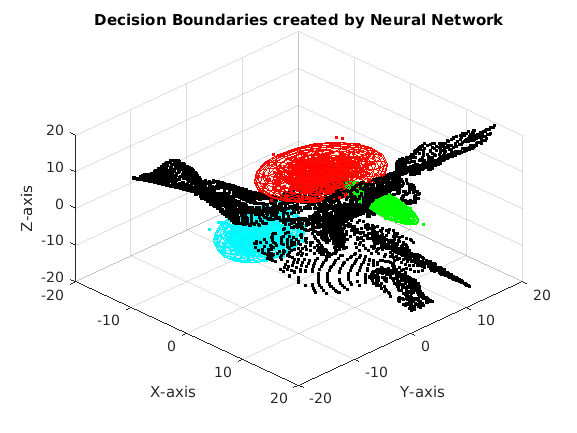


    inputVector = horzcat(a.y', a.z',a.W');
    trueclassindices = [ 1 2 3];
    One_hot_encoded = full(ind2vec(trueclassindices,3));
    label_A = repmat(One_hot_encoded(1,:), a.K,1);
    label_B = repmat(One_hot_encoded(2,:),a.K,1);
    label_C = repmat(One_hot_encoded(3,:), a.K,1);
    target_label = horzcat(label_A',label_B',label_C');
% 
% Training the neural network 10 times
 for index = 1:10

     inputs = inputVector;
     targets = target_label;
     hiddenLayerSize = 50;
     net = patternnet(hiddenLayerSize);
     net.divideParam.trainRatio = 70/100;
     net.divideParam.valRatio = 15/100;
     net.divideParam.testRatio = 15/100;
     [net,~] = train(net,inputs,targets);
    
     
     points= vol3D([-15 20 -15 20 -15 20],150);
     results = net(points');
     g = results';
     
     [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)
%     
%     % plotting the decision boundary boundary created by neural network
     Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
     title('Decision Boundaries created by Neural Network')
   
 end

**4.3** **Change in Neural Network Boundaries with the increase in number of neurons**

We keep the weights same while increasing the number of hidden layers

Case1 : Hidden Layer size 10

points= vol3D([-15 20 -15 20 -15 20],150);
    inputs = inputVector;
    targets = target_label;
    hiddenLayerSize = 10;
    net = patternnet(hiddenLayerSize);
    net.divideParam.trainRatio = 70/100;
    net.divideParam.valRatio = 15/100;
    net.divideParam.testRatio = 15/100;
    rng(1)
    [net,tr] = train(net,inputs,targets);
    results = net(points');
    g = results';
    subplot(2, 2, 1);
    [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =     2.3826   17.4161  -11.7114
    2.3826   18.1208  -12.1812
    2.3826   18.3557  -12.4161
    2.3826   18.5906  -12.4161
    2.3826   18.8255  -12.6510
    2.3826   19.2953  -12.8859
    2.3826   19.5302  -13.1208
    2.3826   19.7651  -13.1208
    2.3826   20.0000  -13.3557
    2.6174   14.1275   -9.3624


boundary_2 =   -15.0000  -15.0000   11.3087
  -15.0000  -10.5369    6.8456
  -15.0000   -8.8926    4.9664
  -15.0000   -4.6644    0.7383
  -15.0000   -3.2550   -0.4362
  -15.0000   -1.6107   -1.8456
  -15.0000    0.0336   -3.2550
  -15.0000    0.2685   -3.4899
  -15.0000    2.3826   -5.3691
  -15.0000    4.2617   -7.0134


boundary_3 =     1.9128    6.8456   -2.5503
    1.9128    7.0805   -2.5503
    1.9128    7.7852   -2.7852
    1.9128    8.4899   -3.0201
    1.9128    9.1946   -3.2550
    1.9128    9.8993   -3.4899
    1.9128   10.3691   -3.7248
    1.9128   10.8389   -3.9597
    2.1477    5.6711   -1.8456
    2.1477    6.8456   -2.0805


    
    % plotting the decision boundary created by neural network
    Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
    title('Decision Boundaries created by Neural Network with 10 hidden layers')

Case 2: Hidden Layer Size 30

inputs = inputVector;
    targets = target_label;
    hiddenLayerSize = 30;
    net30 = patternnet(hiddenLayerSize);
    net30.divideParam.trainRatio = 70/100;
    net30.divideParam.valRatio = 15/100;
    net30.divideParam.testRatio = 15/100;
    rng(1)
    [net30,tr] = train(net30,inputs,targets);
    results = net30(points');
    g = results';
    subplot(2, 2, 2);
    [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =    -0.2013    8.9597  -14.0604
    0.0336    8.4899  -13.1208
    0.2685    8.4899  -13.3557
    0.5034    8.0201  -12.4161
    0.5034    8.7248  -14.2953
    0.9732    7.5503  -11.7114
    0.9732    8.2550  -13.5906
    1.2081    6.8456  -10.0671
    1.2081    7.7852  -12.6510
    1.4430    6.6107   -9.5973


boundary_2 =   -15.0000   -8.8926    5.9060
  -15.0000   -7.2483    4.0268
  -15.0000   -5.3691    1.6779
  -15.0000   -3.4899   -1.1409
  -15.0000   -2.7852   -2.3154
  -15.0000   -2.0805   -3.4899
  -15.0000   -0.4362   -5.3691
  -15.0000    1.9128   -6.7785
  -15.0000    2.3826   -7.0134
  -15.0000    4.0268   -7.9530


boundary_3 =    -4.8993   19.7651  -15.0000
   -4.8993   19.7651  -14.7651
   -4.8993   19.7651  -14.5302
   -4.8993   20.0000  -13.8255
   -4.8993   20.0000  -13.5906
   -4.8993   20.0000  -13.3557
   -4.8993   20.0000  -13.1208
   -4.6644   19.0604  -15.0000
   -4.6644   19.2953  -14.5302
   -4.6644   19.2953  -14.2953


    
    % plotting the decision boundary created by neural network
    Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
    title('Decision Boundaries created by Neural Network with 30 hidden layers')

Case 3: Hidden Layer size 60

inputs = inputVector;
    targets = target_label;
    hiddenLayerSize = 60;
    net60 = patternnet(hiddenLayerSize);
    net60.divideParam.trainRatio = 70/100;
    net60.divideParam.valRatio = 15/100;
    net60.divideParam.testRatio = 15/100;
    rng(1)
    [net60,tr] = train(net60,inputs,targets);
    results = net60(points');
    g = results';
    subplot(2, 2, 3);
    [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =    -1.3758  -14.7651    5.2013
   -1.1409  -15.0000    4.9664
   -1.1409  -14.7651    5.2013
   -0.9060  -15.0000    4.9664
   -0.9060  -14.7651    5.2013
   -0.6711  -15.0000    4.9664
   -0.6711  -14.7651    5.2013
    0.2685  -15.0000    5.2013
    1.6779    4.7315   -2.5503
    1.6779    6.3758   -3.7248


boundary_2 =   -15.0000  -14.2953   -1.8456
  -15.0000  -13.3557   -2.0805
  -15.0000  -13.1208   -2.0805
  -15.0000  -12.1812   -2.3154
  -15.0000  -11.9463   -2.3154
  -15.0000  -11.7114   -2.3154
  -15.0000  -11.4765   -2.3154
  -15.0000  -10.5369   -2.0805
  -15.0000   -9.1275   -1.3758
  -15.0000   -8.4228   -1.1409


boundary_3 =     1.4430    6.6107   -0.4362
    1.4430    7.5503   -1.6107
    1.6779    3.5570    1.4430
    1.6779    4.7315    1.2081
    1.6779    6.3758    0.2685
    1.6779    6.6107    0.0336
    1.6779    6.8456   -0.2013
    1.6779    7.0805   -0.4362
    1.6779    8.0201   -1.6107
    1.9128    2.3826    1.6779


    
    % plotting the decision boundary created by neural network
    Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
    title('Decision Boundaries created by Neural Network with 60 hidden layers')
    

Case 3: Hidden Layer size 100

inputs = inputVector;
    targets = target_label;
    hiddenLayerSize = 100;
    net100 = patternnet(hiddenLayerSize);
    net100.divideParam.trainRatio = 70/100;
    net100.divideParam.valRatio = 15/100;
    net100.divideParam.testRatio = 15/100;
    rng(1)
    [net100,tr] = train(net100,inputs,targets);
    results = net100(points');
    g = results';
    subplot(2, 2, 4);
    [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =    -7.2483  -15.0000    4.0268
   -6.0738  -14.2953    3.5570
   -6.0738  -13.5906    3.5570
   -5.3691  -14.0604    3.3221
   -5.3691  -13.3557    3.3221
   -4.6644  -11.7114    3.3221
   -4.4295  -13.3557    3.0872
   -4.1946  -12.6510    3.0872
   -3.9597  -11.0067    3.3221
   -3.7248  -12.1812    3.0872


boundary_2 =   -15.0000  -14.2953    5.9060
  -15.0000  -14.0604    5.9060
  -15.0000  -11.9463    5.6711
  -15.0000  -10.5369    5.2013
  -15.0000   -5.6040    2.8523
  -15.0000   -4.8993    2.6174
  -15.0000   -3.4899    2.6174
  -15.0000   -2.3154    2.8523
  -15.0000   -0.2013    2.6174
  -15.0000    4.4966   -0.9060


boundary_3 =   -11.4765  -15.0000   18.5906
  -11.4765  -15.0000   18.8255
  -11.2416  -15.0000   12.9530
  -11.2416  -15.0000   13.1879
  -11.2416  -15.0000   13.4228
  -11.2416  -14.7651   19.2953
  -11.0067  -14.7651   12.2483
  -11.0067  -14.7651   12.4832
  -11.0067  -14.5302   19.7651
  -11.0067  -14.5302   20.0000


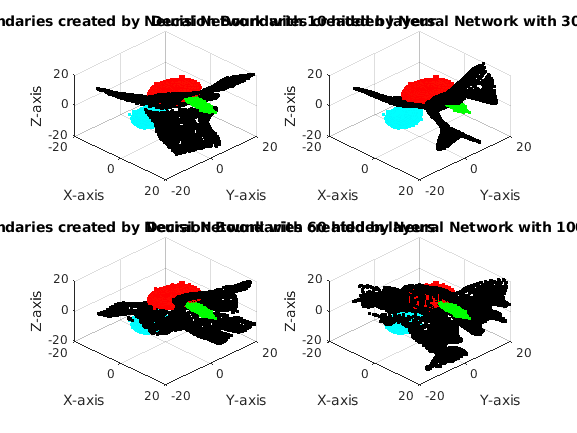

    
    % plotting the decision boundary created by neural network
    Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
    title('Decision Boundaries created by Neural Network with 100 hidden layers')

4. **Discussion for variability in the produced class decision boundaries**

Training the neural network with random seeds assigns different weights to the hidden layers and hence, different outputs are produced by the neural network on each iteration. Setting the random seed to a constant can produce the same neural network boundaries on each iteration. 

4.1.**Discuss what would occur relative to the produced decision boundaries if 100 different neural network trainings were conducted.**

From the above experiment we observe that on each iteration, the neural network with random seeds produced different boundaries. Therefore, it is expected that the decision boundaries would vary even if the neural network is trained 100 times due to the random weights that are captured on each iteration of trainings. Due to the different random weights, at every iteration a different function is generated for training the neural network. Therefore, a different function will be generated even if we train the neural network 100 times.

4.2.** Discuss which of the resulting neural network decision boundaries is the correct (or more correct) boundary.**

 The neural network decision boundaries are not 100% correct boundaries as we observed in comparison with the bayesian boundaries generated with the same.

Further, none of the resulting neural network decision boundaries is correct (or more correct) boundary as each of the neural networks is provided with the same amount and type of data. Each neural network is just producing 3 different separations for the data using the random functions. . 

4.3. **Discuss how the nature of the neural network decision boundaries would change as increasingly more neurons are added to the neural network's hidden layer(s).**

With the increase in the number of neural network decision boundaries, the complexity of the produced decision boundaries seem to increase as more number of functions within the hidden layers get added to produce the classification. More number of neurons also increase the speed of data classification and produces fasters results.

function [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)
    epsilon_NN_1 = 1e-1;
    epsilon_NN_2 = 1e-2; 
    decisionbound1 =  abs(g(:, 1) - g(:, 2));
    decisionbound2 =  abs(g(:, 2) - g(:, 3));
    decisionbound3 =  abs(g(:, 1) - g(:, 3));
    
    ind_boundary_1 = find(abs(g(:, 1)) <= epsilon_NN_1 & decisionbound2 < epsilon_NN_2);
    ind_boundary_2 = find(abs(g(:, 2)) <= epsilon_NN_1 & decisionbound3 < epsilon_NN_2);
    ind_boundary_3 = find(abs(g(:, 3)) <= epsilon_NN_1 & decisionbound1 < epsilon_NN_2);    
    boundary_1 = points(ind_boundary_1,:);
    boundary_2 = points(ind_boundary_2,:);
    boundary_3 = points(ind_boundary_3,:);        
end

function [] = ellipsoid_plot(mu,sigma,edge_color)
[V,D] = eigs(sigma);
std = sqrt(diag(D));

% obtaining position values using ellipsoid function, the ellipsoid
% function uses one, two and three standard deviation from the mean
[x1,y1,z1] = ellipsoid(0,0,0,std(1),std(2),std(3));
[x2,y2,z2] = ellipsoid(0,0,0,2*std(1),2*std(2),2*std(3));
[x3,y3,z3] = ellipsoid(0,0,0,3*std(1),3*std(2),3*std(3));    


% adjusting the position values of all the three different standard
% deviations

% plotting concentric ellipsoid 1 with one standard deviation

dim = [x1(:) y1(:) z1(:)]'; 
dim = V*dim + mu; % adjusting the mean
x1 = reshape(dim(1,:), size(x1));
y1 = reshape(dim(2,:), size(y1));
z1 = reshape(dim(3,:), size(z1));


surf(x1,y1,z1,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 2 with two standard deviation
dim = [x2(:) y2(:) z2(:)]';
dim = V*dim + mu;
x2 = reshape(dim(1,:), size(x2));
y2 = reshape(dim(2,:), size(y2));
z2 = reshape(dim(3,:), size(z2));


surf(x2,y2,z2,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 3 with three standard deviation
dim = [x3(:) y3(:) z3(:)]';
dim = V*dim + mu;
x3 = reshape(dim(1,:), size(x3));
y3 = reshape(dim(2,:), size(y3));
z3 = reshape(dim(3,:), size(z3));


surf(x3,y3,z3,'FaceAlpha',0.05,'EdgeColor',edge_color);
end

function [] = Classes(randomClassASamples,muClassA,sigmaClassA,randomClassBSamples,muClassB,sigmaClassB,randomClassCSamples,muClassC,sigmaClassC,boundary_1,boundary_2,boundary_3, color)
    
    ellipsoid_plot(muClassA,sigmaClassA,[1 0 0])
    hold on
    ellipsoid_plot(muClassB,sigmaClassB,[0 1 0])
    ellipsoid_plot(muClassC,sigmaClassC,[0 1 1])
    
    scatter3(randomClassASamples(:,1),randomClassASamples(:,2),randomClassASamples(:,3),'r.')
    scatter3(randomClassBSamples(:,1),randomClassBSamples(:,2),randomClassBSamples(:,3),'g.')
    scatter3(randomClassCSamples(:,1),randomClassCSamples(:,2),randomClassCSamples(:,3),'c.')
    plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",color)
    hold off
    xlabel('X-axis')
    ylabel('Y-axis')
    zlabel('Z-axis')
    view([45 45])
end

function V = vol3D(Vaxis,Num)
% Build 3D volume of regular grid points 

    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a - min_a) / (NV - 1);
    %r = min_a: res: max_a;
    %r = r(:);
    rx = [Vaxis(1):(Vaxis(2) - Vaxis(1)) / (NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4) - Vaxis(3)) / (NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6) - Vaxis(5)) / (NV-1):Vaxis(6)]';
    x = zeros(3, length(rz)^3);
    k = 1;
    j = 1;
    
    for i = 1:length(rz):length(x)
        x(3, (i - 1) + (1: length(rz))) = rz;
        x(2, (i - 1) + (1: length(rz))) = ry(k) * ones(1, length(rz));
        x(1, (i - 1) + (1: length(rz))) = rx(j) * ones(1, length(rz));
        k = k + 1;
        if k > length(rz)
            k = 1;
            j = j + 1;
        end
    end
    x = x';
    V = x;

end
